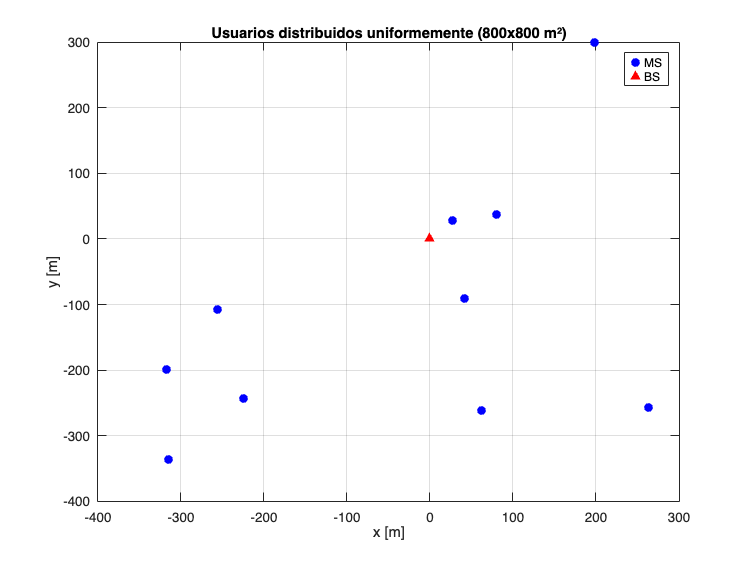

Usuario seleccionado final: 7      Vector de retardo final: 3000  3000   751  3000  3000  1794     0  3000  3000     2


Usuario seleccionado final: 9      Vector de retardo final: 3000  3000  3000  3000   377  1291  3000  3000     0  3000


Usuario seleccionado final: 3      Vector de retardo final: 1041  3000     0  3000  3000   467  3000   197  3000  3000


Usuario seleccionado final: 4      Vector de retardo final: 3000   474  3000     0  3000  3000  3000  3000  3000     2


Usuario seleccionado final: 9      Vector de retardo final: 7  3000  3000  3000  1563  3000  2295  3000     0  3000


Usuario seleccionado final: 9      Vector de retardo final: 2081  3000  3000  3000   105  3000  3000  3000     0   954


Usuario seleccionado final: 10      Vector de retardo final: 2314    13  3000  3000  3000  1689  3000   543   916     0


Usuario seleccionado final: 2      Vector de retardo final: 3000     0  3000  3000    41  3000  3000  1144  3000  3000


Usuario seleccionado final: 5      Vector de retardo final: 3000   135  3000  3000     0  3000    10  3000     9  3000


Usuario seleccionado final: 10      Vector de retardo final: 3000  3000  3000  3000  3000  3000     4  3000  3000     0


Usuario seleccionado final: 8      Vector de retardo final: 3000  3000  3000    15   129  3000  3000     0  2582  3000


Usuario seleccionado final: 3      Vector de retardo final: 3000  1306     0   613  3000  3000    43  3000    17     4


Usuario seleccionado final: 3      Vector de retardo final: 3000  3000     0    10    39  3000  3000  3000  3000  3000


Usuario seleccionado final: 9      Vector de retardo final: 3000  3000  3000  3000  3000  3000    19  3000     0  3000


Usuario seleccionado final: 9      Vector de retardo final: 3000  3000  3000  3000  3000  3000   518  3000     0  3000


Usuario seleccionado final: 4      Vector de retardo final: 3000  3000  3000     0     4  3000   707  3000  3000  3000


Usuario seleccionado final: 9      Vector de retardo final: 3000  3000  3000    65     1  3000  3000  2372     0    63


Usuario seleccionado final: 2      Vector de retardo final: 3000     0  3000     1  3000   277  3000  3000  3000  3000


Usuario seleccionado final: 4      Vector de retardo final: 2    12  3000     0  3000     4   217  3000     9   128


Usuario seleccionado final: 10      Vector de retardo final: 3000  3000  3000  3000  3000  3000  3000  3000  3000     0


clear all; clc;

% ---------------------------------------------
% Parámetros del sistema
% ---------------------------------------------
B = 10*10^6;            % Ancho de banda de 10 MHz
f = 1.8*10^9;           % Frecuencia portadora de 1.8 GHz
Ptx = 20;               % Potencia de transmisión en vatios (20 W)
num_muestras = 96000;    % Número total de muestras a simular inicialmente
N0 = 10^-20;            % Densidad espectral de ruido (W/Hz)
sigma_sh = 1.5;         % Desviación típica del shadowing log-normal (dB)
fd_values = [5 50 120]; % Tres valores posibles de frecuencia de Doppler (baja, media, alta)
ts = 1/B;               % Tiempo de símbolo = inverso del ancho de banda

% ---------------------------------------------
% Estación base y usuarios
% ---------------------------------------------
Pos_BS = 0 + 1i * 0;
K = 10;

% Inicialización de acumuladores
retardos_all = cell(K, 1);
BER_all = cell(K, 1);
tasa_all = cell(K, 1);

nbrofSetups = 20;

% Montecarlo con Frecuencia Doppler = 5 y algoritmo maxsnr
for i = 1:nbrofSetups
    % --------------------------------------
    % Opción 1: Área rectangular 800x800 m
    % --------------------------------------
    lado_x = 800;
    lado_y = 800;
    option1 = 1;
    Pos_MS1 = Calc_Pos_MS(option1, K, 0, 0, lado_x, lado_y);

    % -----------------------
    % Visualización
    % -----------------------
    figure;
    plot(real(Pos_MS1), imag(Pos_MS1), 'bo', 'MarkerFaceColor', 'b');
    hold on;
    plot(real(Pos_BS), imag(Pos_BS), 'r^', 'MarkerFaceColor', 'r');
    title('Usuarios distribuidos uniformemente (800x800 m²)');
    xlabel('x [m]'); ylabel('y [m]');
    grid on; legend('MS','BS');

    % ---------------------------------------------
    % SNR por usuario
    % ---------------------------------------------
    SNRs = zeros(K, 1);
    for k = 1:K
        dist = abs(Pos_BS - Pos_MS1(k));
        SNRs(k) = calcular_SNRs(Pos_BS, Pos_MS1(k), Ptx, B, f, sigma_sh, N0);
    end

    % ---------------------------------------------
    % Visualización de las SNRs de los usuarios
    % ---------------------------------------------
    figure;
    bar(SNRs);
    title('SNR de los Usuarios');
    xlabel('Usuario'); 
    ylabel('SNR [dB]'); 
    grid on;

    % ---------------------------------------------
    % Parámetros de simulación y Scheduler
    % ---------------------------------------------
    SNR_avg = mean(SNRs);
    delay_vector = zeros(1, K);
    num_tramas = num_muestras / 32;
    algoritmo = 'maxsnr';

    % --- Simulación con frecuencia de Doppler = 5 Hz ---
    h = Apply_Rayleigh_Channel(SNRs, fd_values(1), num_muestras, ts);
    h = h(:, 1:32:end);
    SNR_dB = 20 * log10(abs(h));

    [selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = ...
        Scheduler(SNR_dB, delay_vector, SNR_avg, algoritmo, num_tramas);

    plotMeanDelay(retardos);
    disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

    % --- Determinar modulación por trama ---
    M_vector = zeros(1, num_tramas);
    for t = 1:num_tramas
        user = selected_users(t);
        M_vector(t) = Select_Modulation(SNR_dB(user, t));
    end

    % --- Generación de bits total según modulación ---
    bits_per_user = accumarray(selected_users.', log2(M_vector).');
    max_bits = max(bits_per_user);
    btx = randi([0 1], K, max_bits);

    % --- Transmisión adaptativa ---
    [brx, y, tasa_k] = Transmit_AdaptiveQAM(btx, selected_users, h, M_vector,B);

    % --- BER esperada con modulación adaptativa ---
    BER_k = Calculate_BER_Adaptive(SNR_dB, selected_users);

    figure;
    bar(BER_k);
    title('BER media de los Usuarios (modulación adaptativa)');
    xlabel('Usuarios'); 
    ylabel('BER'); 
    grid on;

    % --- Acumulación por usuario ---
    for k = 1:K
        retardos_all{k} = [retardos_all{k}, retardos{k}];
        BER_all{k} = [BER_all{k}, BER_k(k)];
        tasa_all{k} = [tasa_all{k}, tasa_k(k)];
    end

    % --- PDF del número total de tramas de espera ---
    all_delays = cell2mat(retardos);
    total_tramas_espera = sum(all_delays);

    figure;
    histogram(all_delays, 'Normalization', 'pdf');
    xlabel('Número de tramas de espera'); ylabel('PDF');
    title('PDF del número de tramas de espera por usuario'); grid on;

    total_delays_per_user = cellfun(@sum, retardos);

    figure;
    bar(1:K, total_delays_per_user);
    xlabel('Usuario'); ylabel('Total de tramas de espera');
    title('Total de tramas de espera por usuario'); grid on;
end


% --- CDF del retardo medio por usuario ---
% Cada celda de retardos_all{k} contiene los retardos acumulados del usuario k
retardo_medio_por_usuario = cellfun(@mean, retardos_all);     
retardo_ordenado = sort(retardo_medio_por_usuario);
cdf_retardo = linspace(0, 1, length(retardo_ordenado));
figure;
plot(retardo_ordenado, cdf_retardo, 'r-', 'LineWidth', 2);
xlabel('Retardo medio [tramas]');
ylabel('CDF');
title('CDF del retardo medio por usuario');
grid on;
ylim([0 1]);


% --- CDF de la BER media por usuario ---
% Cada celda de BER_all{k} contiene las BERs acumuladas del usuario k
ber_media_por_usuario = cellfun(@mean, BER_all);              
ber_ordenado = sort(ber_media_por_usuario);
cdf_ber = linspace(0, 1, length(ber_ordenado));
figure;
plot(ber_ordenado, cdf_ber, 'b-', 'LineWidth', 2);
xlabel('BER Media');
ylabel('CDF');
title('CDF de la BER media por usuario');
grid on;
ylim([0 1]);


% --- CDF de la tasa transmitida por usuario ---
% Cada celda de tasa_all{k} contiene las tasas acumuladas del usuario k
tasa_media_por_usuario = cellfun(@mean, tasa_all);           
tasa_ordenada = sort(tasa_media_por_usuario);
cdf_tasa = linspace(0, 1, length(tasa_ordenada));
figure;
plot(tasa_ordenada, cdf_tasa, 'k-', 'LineWidth', 2);
xlabel('Tasa transmitida por usuario [Mb/s]');
ylabel('CDF');
title('CDF de la tasa transmitida por usuario');
grid on;
ylim([0 1]);


%Inicializo las variables nuevamente para realizar las futuras simulaciones
retardos_all = cell(K, 1);   
BER_all = cell(K, 1);        
tasa_all = cell(K, 1);       
delay_vector = zeros(1, K);  
selected_users = [];

% Montecarlo con Frecuencia Doppler = 50 y algoritmo de maxsnr
for i = 1:nbrofSetups
    % --------------------------------------
    % Opción 1: Área rectangular 800x800 m
    % --------------------------------------
    lado_x = 800;
    lado_y = 800;
    option1 = 1;
    Pos_MS1 = Calc_Pos_MS(option1, K, 0, 0, lado_x, lado_y);

    % -----------------------
    % Visualización
    % -----------------------
    figure;
    plot(real(Pos_MS1), imag(Pos_MS1), 'bo', 'MarkerFaceColor', 'b');
    hold on;
    plot(real(Pos_BS), imag(Pos_BS), 'r^', 'MarkerFaceColor', 'r');
    title('Usuarios distribuidos uniformemente (800x800 m²)');
    xlabel('x [m]'); ylabel('y [m]');
    grid on; legend('MS','BS');

    % ---------------------------------------------
    % SNR por usuario
    % ---------------------------------------------
    SNRs = zeros(K, 1);
    for k = 1:K
        dist = abs(Pos_BS - Pos_MS1(k));
        SNRs(k) = calcular_SNRs(Pos_BS, Pos_MS1(k), Ptx, B, f, sigma_sh, N0);
    end

    % ---------------------------------------------
    % Visualización de las SNRs de los usuarios
    % ---------------------------------------------
    figure;
    bar(SNRs);
    title('SNR de los Usuarios');
    xlabel('Usuario'); 
    ylabel('SNR [dB]'); 
    grid on;

    % ---------------------------------------------
    % Parámetros de simulación y Scheduler
    % ---------------------------------------------
    SNR_avg = mean(SNRs);
    delay_vector = zeros(1, K);
    num_tramas = num_muestras / 32;
    algoritmo = 'maxsnr';

    % --- Simulación con frecuencia de Doppler = 50 Hz ---
    h = Apply_Rayleigh_Channel(SNRs, fd_values(2), num_muestras, ts);
    h = h(:, 1:32:end);
    SNR_dB = 20 * log10(abs(h));

    [selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = ...
        Scheduler(SNR_dB, delay_vector, SNR_avg, algoritmo, num_tramas);

    plotMeanDelay(retardos);
    disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

    % --- Determinar modulación por trama ---
    M_vector = zeros(1, num_tramas);
    for t = 1:num_tramas
        user = selected_users(t);
        M_vector(t) = Select_Modulation(SNR_dB(user, t));
    end

    % --- Generación de bits total según modulación ---
    bits_per_user = accumarray(selected_users.', log2(M_vector).');
    max_bits = max(bits_per_user);
    btx = randi([0 1], K, max_bits);

    % --- Transmisión adaptativa ---
    [brx, y, tasa_k] = Transmit_AdaptiveQAM(btx, selected_users, h, M_vector,B);

    % --- BER esperada con modulación adaptativa ---
    BER_k = Calculate_BER_Adaptive(SNR_dB, selected_users);

    figure;
    bar(BER_k);
    title('BER media de los Usuarios (modulación adaptativa)');
    xlabel('Usuarios'); 
    ylabel('BER'); 
    grid on;

    % --- Acumulación por usuario ---
    for k = 1:K
        retardos_all{k} = [retardos_all{k}, retardos{k}];
        BER_all{k} = [BER_all{k}, BER_k(k)];
        tasa_all{k} = [tasa_all{k}, tasa_k(k)];
    end

    % --- PDF del número total de tramas de espera ---
    all_delays = cell2mat(retardos);
    total_tramas_espera = sum(all_delays);

    figure;
    histogram(all_delays, 'Normalization', 'pdf');
    xlabel('Número de tramas de espera'); ylabel('PDF');
    title('PDF del número de tramas de espera por usuario'); grid on;

    total_delays_per_user = cellfun(@sum, retardos);

    figure;
    bar(1:K, total_delays_per_user);
    xlabel('Usuario'); ylabel('Total de tramas de espera');
    title('Total de tramas de espera por usuario'); grid on;
end

% --- CDF del retardo medio por usuario ---
% Cada celda de retardos_all{k} contiene los retardos acumulados del usuario k
retardo_medio_por_usuario = cellfun(@mean, retardos_all);     
retardo_ordenado = sort(retardo_medio_por_usuario);
cdf_retardo = linspace(0, 1, length(retardo_ordenado));
figure;
plot(retardo_ordenado, cdf_retardo, 'r-', 'LineWidth', 2);
xlabel('Retardo medio [tramas]');
ylabel('CDF');
title('CDF del retardo medio por usuario');
grid on;
ylim([0 1]);

% --- CDF de la BER media por usuario ---
% Cada celda de BER_all{k} contiene las BERs acumuladas del usuario k
ber_media_por_usuario = cellfun(@mean, BER_all);              
ber_ordenado = sort(ber_media_por_usuario);
cdf_ber = linspace(0, 1, length(ber_ordenado));
figure;
plot(ber_ordenado, cdf_ber, 'b-', 'LineWidth', 2);
xlabel('BER Media');
ylabel('CDF');
title('CDF de la BER media por usuario');
grid on;
ylim([0 1]);

% --- CDF de la tasa transmitida por usuario ---
% Cada celda de tasa_all{k} contiene las tasas acumuladas del usuario k
tasa_media_por_usuario = cellfun(@mean, tasa_all);           
tasa_ordenada = sort(tasa_media_por_usuario);
cdf_tasa = linspace(0, 1, length(tasa_ordenada));
figure;
plot(tasa_ordenada, cdf_tasa, 'k-', 'LineWidth', 2);
xlabel('Tasa transmitida por usuario [Mb/s]');
ylabel('CDF');
title('CDF de la tasa transmitida por usuario');
grid on;
ylim([0 1]);

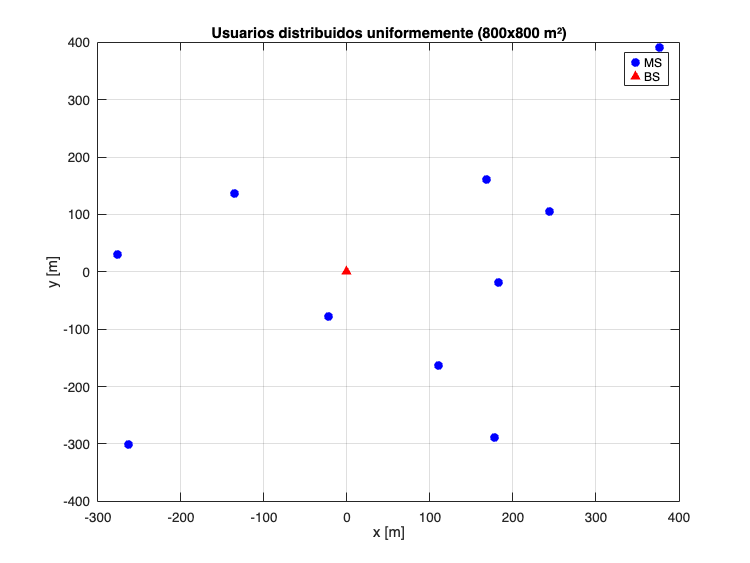

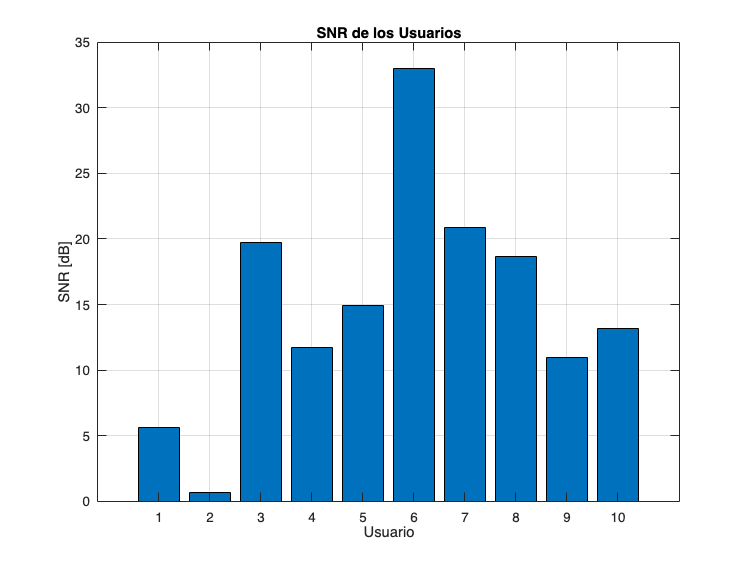

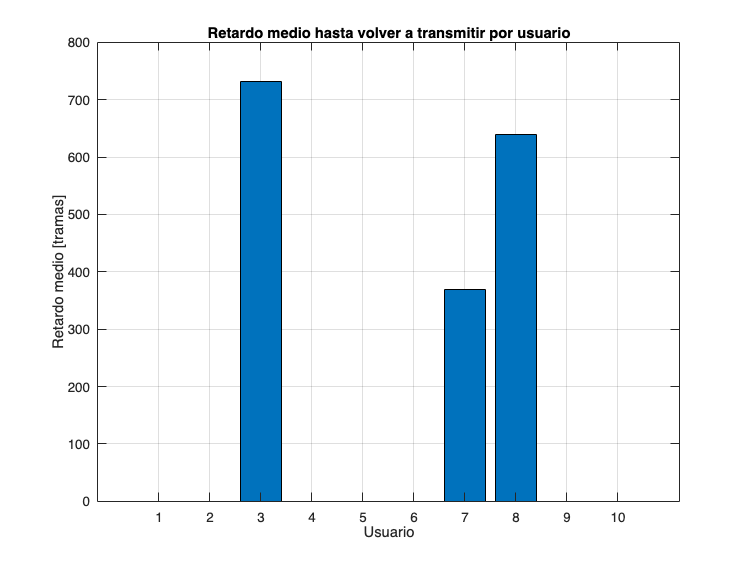

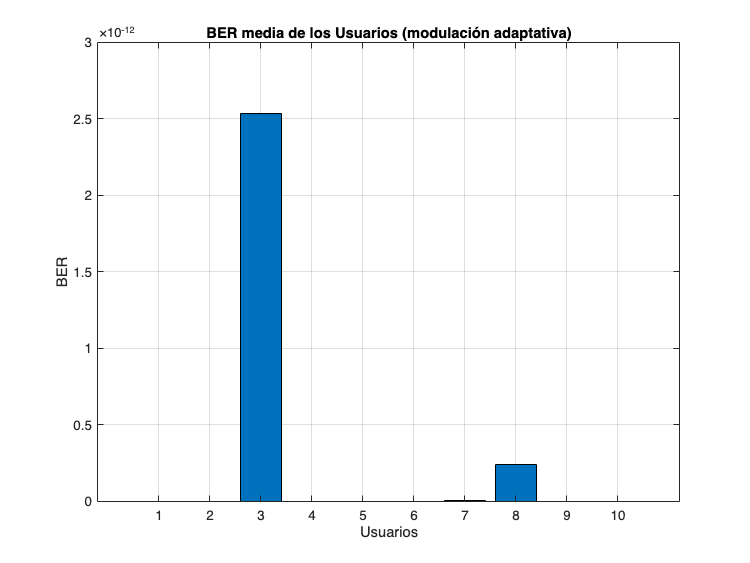

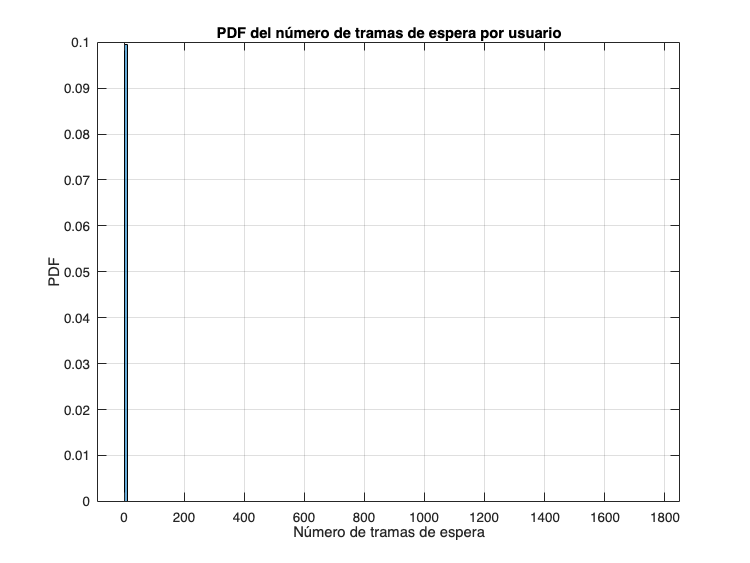

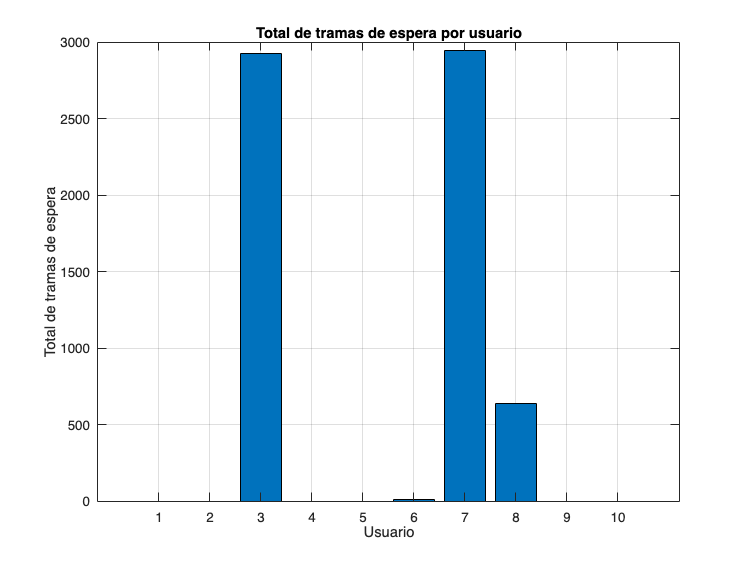

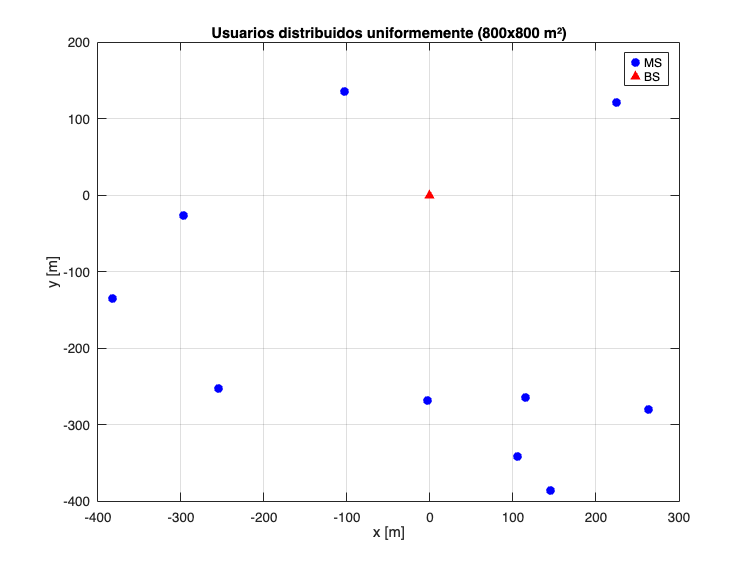

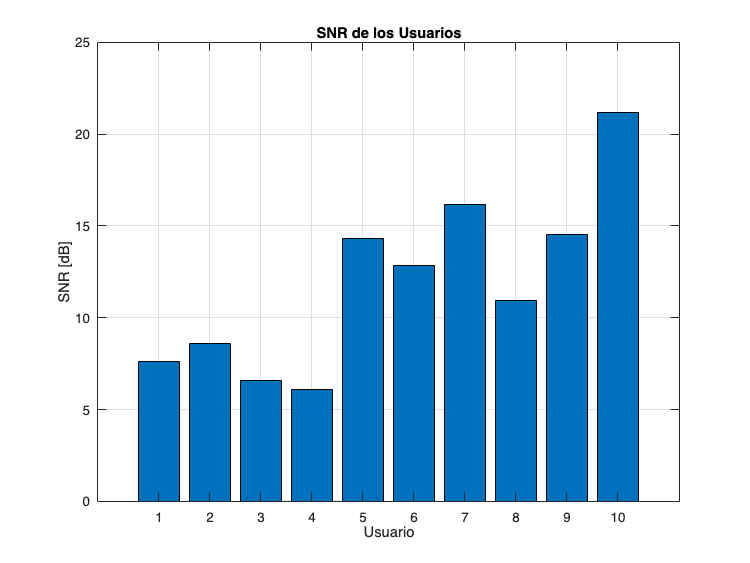

%Inicializo las variables nuevamente para realizar las futuras simulaciones
retardos_all = cell(K, 1);   
BER_all = cell(K, 1);        
tasa_all = cell(K, 1);       
delay_vector = zeros(1, K);  
selected_users = [];

% Montecarlo con Frecuencia Doppler = 120 y algoritmo maxsnr
for i = 1:nbrofSetups
    % --------------------------------------
    % Opción 1: Área rectangular 800x800 m
    % --------------------------------------
    lado_x = 800;
    lado_y = 800;
    option1 = 1;
    Pos_MS1 = Calc_Pos_MS(option1, K, 0, 0, lado_x, lado_y);

    % -----------------------
    % Visualización
    % -----------------------
    figure;
    plot(real(Pos_MS1), imag(Pos_MS1), 'bo', 'MarkerFaceColor', 'b');
    hold on;
    plot(real(Pos_BS), imag(Pos_BS), 'r^', 'MarkerFaceColor', 'r');
    title('Usuarios distribuidos uniformemente (800x800 m²)');
    xlabel('x [m]'); ylabel('y [m]');
    grid on; legend('MS','BS');

    % ---------------------------------------------
    % SNR por usuario
    % ---------------------------------------------
    SNRs = zeros(K, 1);
    for k = 1:K
        dist = abs(Pos_BS - Pos_MS1(k));
        SNRs(k) = calcular_SNRs(Pos_BS, Pos_MS1(k), Ptx, B, f, sigma_sh, N0);
    end

    % ---------------------------------------------
    % Visualización de las SNRs de los usuarios
    % ---------------------------------------------
    figure;
    bar(SNRs);
    title('SNR de los Usuarios');
    xlabel('Usuario'); 
    ylabel('SNR [dB]'); 
    grid on;

    % ---------------------------------------------
    % Parámetros de simulación y Scheduler
    % ---------------------------------------------
    SNR_avg = mean(SNRs);
    delay_vector = zeros(1, K);
    num_tramas = num_muestras / 32;
    algoritmo = 'maxsnr';

    % --- Simulación con frecuencia de Doppler = 120 Hz ---
    h = Apply_Rayleigh_Channel(SNRs, fd_values(3), num_muestras, ts);
    h = h(:, 1:32:end);
    SNR_dB = 20 * log10(abs(h));

    [selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = ...
        Scheduler(SNR_dB, delay_vector, SNR_avg, algoritmo, num_tramas);

    plotMeanDelay(retardos);
    disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

    % --- Determinar modulación por trama ---
    M_vector = zeros(1, num_tramas);
    for t = 1:num_tramas
        user = selected_users(t);
        M_vector(t) = Select_Modulation(SNR_dB(user, t));
    end

    % --- Generación de bits total según modulación ---
    bits_per_user = accumarray(selected_users.', log2(M_vector).');
    max_bits = max(bits_per_user);
    btx = randi([0 1], K, max_bits);

    % --- Transmisión adaptativa ---
    [brx, y, tasa_k] = Transmit_AdaptiveQAM(btx, selected_users, h, M_vector,B);

    % --- BER esperada con modulación adaptativa ---
    BER_k = Calculate_BER_Adaptive(SNR_dB, selected_users);

    figure;
    bar(BER_k);
    title('BER media de los Usuarios (modulación adaptativa)');
    xlabel('Usuarios'); 
    ylabel('BER'); 
    grid on;

    % --- Acumulación por usuario ---
    for k = 1:K
        retardos_all{k} = [retardos_all{k}, retardos{k}];
        BER_all{k} = [BER_all{k}, BER_k(k)];
        tasa_all{k} = [tasa_all{k}, tasa_k(k)];
    end

    % --- PDF del número total de tramas de espera ---
    all_delays = cell2mat(retardos);
    total_tramas_espera = sum(all_delays);

    figure;
    histogram(all_delays, 'Normalization', 'pdf');
    xlabel('Número de tramas de espera'); ylabel('PDF');
    title('PDF del número de tramas de espera por usuario'); grid on;

    total_delays_per_user = cellfun(@sum, retardos);

    figure;
    bar(1:K, total_delays_per_user);
    xlabel('Usuario'); ylabel('Total de tramas de espera');
    title('Total de tramas de espera por usuario'); grid on;
end

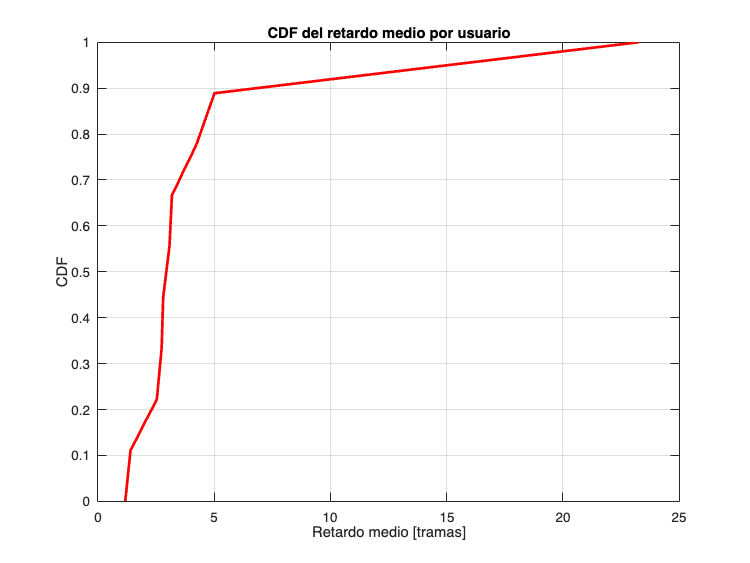

% --- CDF del retardo medio por usuario ---
% Cada celda de retardos_all{k} contiene los retardos acumulados del usuario k
retardo_medio_por_usuario = cellfun(@mean, retardos_all);     
retardo_ordenado = sort(retardo_medio_por_usuario);
cdf_retardo = linspace(0, 1, length(retardo_ordenado));
figure;
plot(retardo_ordenado, cdf_retardo, 'r-', 'LineWidth', 2);
xlabel('Retardo medio [tramas]');
ylabel('CDF');
title('CDF del retardo medio por usuario');
grid on;
ylim([0 1]);

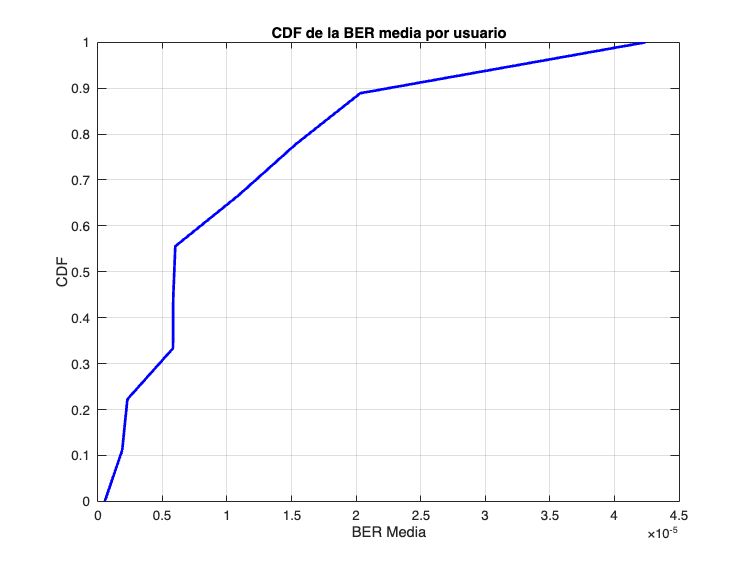


% --- CDF de la BER media por usuario ---
% Cada celda de BER_all{k} contiene las BERs acumuladas del usuario k
ber_media_por_usuario = cellfun(@mean, BER_all);              
ber_ordenado = sort(ber_media_por_usuario);
cdf_ber = linspace(0, 1, length(ber_ordenado));
figure;
plot(ber_ordenado, cdf_ber, 'b-', 'LineWidth', 2);
xlabel('BER Media');
ylabel('CDF');
title('CDF de la BER media por usuario');
grid on;
ylim([0 1]);

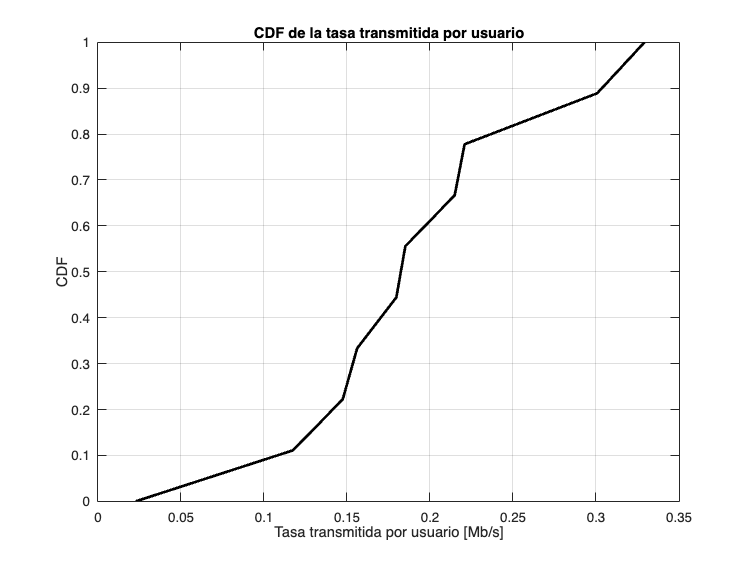


% --- CDF de la tasa transmitida por usuario ---
% Cada celda de tasa_all{k} contiene las tasas acumuladas del usuario k
tasa_media_por_usuario = cellfun(@mean, tasa_all);           
tasa_ordenada = sort(tasa_media_por_usuario);
cdf_tasa = linspace(0, 1, length(tasa_ordenada));
figure;
plot(tasa_ordenada, cdf_tasa, 'k-', 'LineWidth', 2);
xlabel('Tasa transmitida por usuario [Mb/s]');
ylabel('CDF');
title('CDF de la tasa transmitida por usuario');
grid on;
ylim([0 1]);